# **Ayudantía 4  **J. Barraza

A = load('mataveriPREP9999.dat');  
A = errorNaN(A); % apliquen su función de transformar -9999 a NaN.
B = dos_col(A);  % apliquen su función de transformar a 2 columnas.

Se genera la base de datos sin NaN:

datnan = isnan(B(:,2)) ; % detecta NaN
xd = find(datnan == 1) ; % encuentra los NaN (1) 
B1 = B;
B1(xd,:)=[] ;  % B1(:,1)=year sinNaN ;; B1(:,2)=datos sinNaN   

### `Hacer R.L en base de mínimos cuadrados de datos sin NaN`

% POLYFITS: ajusta polinomio a una serie de datos a través de mín. cuadrados (númerico).
pf1 = polyfit(B1(:,1), B1(:,2),1) ; 
pf2 = polyfit(B1(:,1), B1(:,2),2) ;
pf3 = polyfit(B1(:,1), B1(:,2),3) ;

pf4 = polyfit(B1(:,1), B1(:,2),4) ;

% POLYVALS: numérico a gráfico 
pv1 = polyval(pf1, B1(:,1)) ; 
pv2 = polyval(pf2, B1(:,1)) ;
pv3 = polyval(pf3, B1(:,1)) ;
pv4 = polyval(pf4, B1(:,1)) ;


### `Hacer regresión lineal`

ft = fittype('a*x + b'); % Modelo lineal
F = fit(B1(:,1), B1(:,2), ft); 

'poly1' es equivalente a crear ft en caso lineal, y a usar polyfit grado 1. Investigar distintos formatos disponibles! 

### `Graficar:`` con funciones Poly`

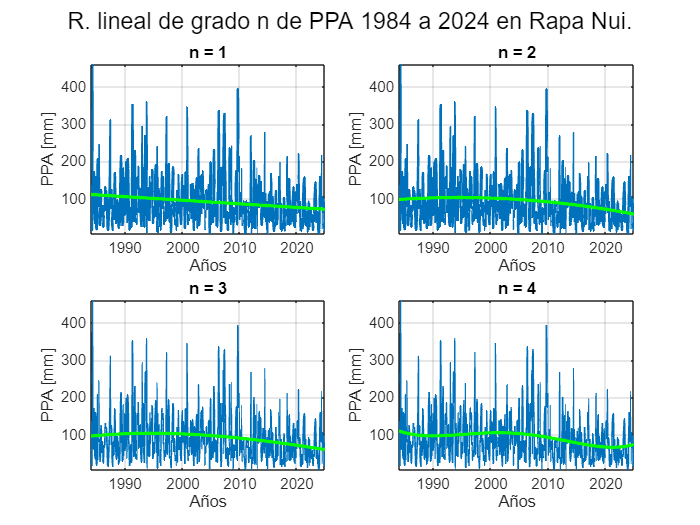

figure(1)
sgtitle('R. lineal de grado n de PPA 1984 a 2024 en Rapa Nui.')
subplot(2,2,1)
  hold on
plot(B1(:,1), B1(:,2),'linewidth', 1.5) 
plot(B1(:,1), pv1, 'g', 'linewidth', 2)
grid on ; box on;
axis tight
title('n = 1')
xlabel('Años')
ylabel('PPA [mm]')

 subplot(2,2,2)
 hold on
plot(B1(:,1), B1(:,2),'linewidth', 1.5) 
plot(B1(:,1), pv2, 'g', 'linewidth', 2)
grid on ; box on;
axis tight
title('n = 2')
xlabel('Años')
ylabel('PPA [mm]')

subplot(2,2,3)
  hold on
plot(B1(:,1), B1(:,2),'linewidth', 1) 
plot(B1(:,1), pv3, 'g', 'linewidth', 2)
grid on ; box on;
axis tight
title('n = 3')
xlabel('Años')
ylabel('PPA [mm]')

subplot(2,2,4)
hold on
plot(B1(:,1), B1(:,2), 'linewidth', 1) 
plot(B1(:,1), pv4, 'g', 'linewidth', 2)
grid on ; box on;
axis tight
title('n = 4')
xlabel('Años')
ylabel('PPA [mm]')

### `Diferencia de polinomio con original`

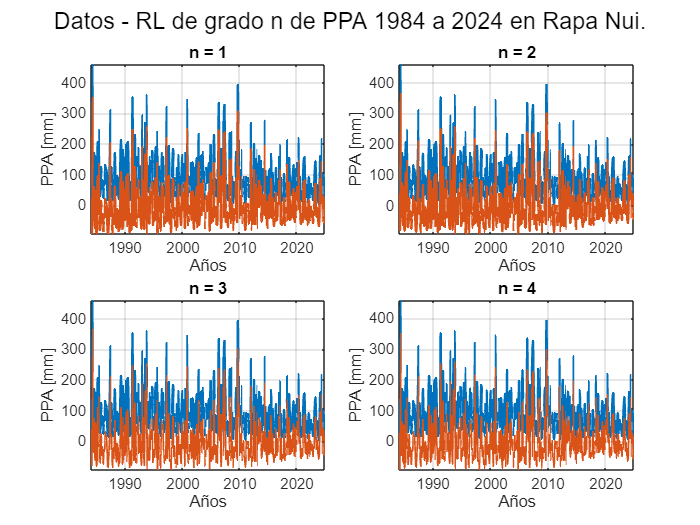

figure(2)
sgtitle('Datos - RL de grado n de PPA 1984 a 2024 en Rapa Nui.')
subplot(2,2,1)
  hold on
plot(B1(:,1), B1(:,2),'linewidth', 1.5)
plot(B1(:,1), B1(:,2)-pv1,'linewidth', 1.5) 
grid on ; box on;
axis tight
title('n = 1')
xlabel('Años')
ylabel('PPA [mm]')

 subplot(2,2,2)
 hold on
plot(B1(:,1), B1(:,2),'linewidth', 1.5)
plot(B1(:,1), B1(:,2)-pv2,'linewidth', 1.5) 
grid on ; box on;
axis tight
title('n = 2')
xlabel('Años')
ylabel('PPA [mm]')

subplot(2,2,3)
  hold on
plot(B1(:,1), B1(:,2),'linewidth', 1.5)
plot(B1(:,1), B1(:,2)-pv3,'linewidth', 1) 
grid on ; box on;
axis tight
title('n = 3')
xlabel('Años')
ylabel('PPA [mm]')

subplot(2,2,4)
hold on
plot(B1(:,1), B1(:,2),'linewidth', 1.5)
plot(B1(:,1), B1(:,2)-pv4, 'linewidth', 1) 
grid on ; box on;
axis tight
title('n = 4')
xlabel('Años')
ylabel('PPA [mm]')

## Con Imaunaloa

C = load('imaunaloaNaN.dat');
C = errorNaN(C);
D = dos_col(C);

D1=D;
datnanD = isnan(D(:,2)) ;
idx = find(datnanD == 1) ;  
D1(idx,:)=[] ;     

%POLYFITS 
pf1D = polyfit(D1(:,1), D1(:,2),1) ;  
pf2D = polyfit(D1(:,1), D1(:,2),2) ;
pf3D = polyfit(D1(:,1), D1(:,2),3) ;

pf4D = polyfit(D1(:,1), D1(:,2),4) ;

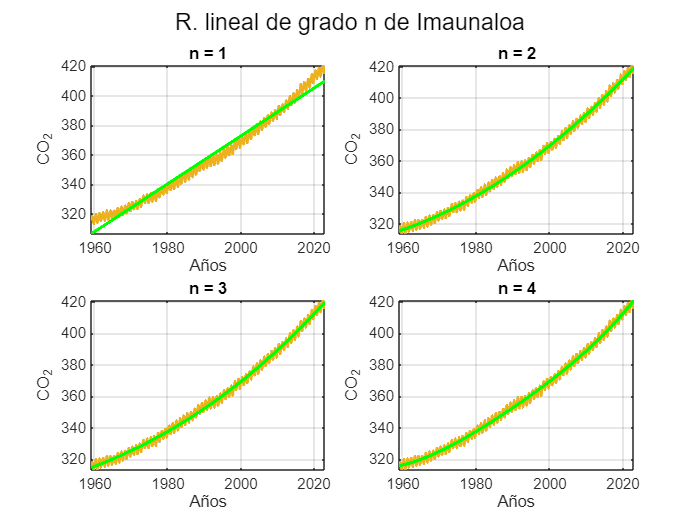


%POLYVALS
pv1D = polyval(pf1D, D1(:,1)) ; 
pv2D = polyval(pf2D, D1(:,1)) ;
pv3D = polyval(pf3D, D1(:,1)) ;
pv4D = polyval(pf4D, D1(:,1)) ;

figure(3)
sgtitle('R. lineal de grado n de Imaunaloa')
subplot(2,2,1)
  hold on
plot(D1(:,1), D1(:,2),'linewidth', 1.5)
plot(D1(:,1), pv1D, 'g','linewidth', 2)
grid on ; box on;
axis tight
title('n = 1')
xlabel('Años')
ylabel('CO_2')
hold off

 subplot(2,2,2)
 hold on
plot(D1(:,1), D1(:,2),'linewidth', 1.5) 
plot(D1(:,1),pv2D, 'g','linewidth', 2)
grid on ; box on;
axis tight
title('n = 2')
xlabel('Años')
ylabel('CO_2')
hold off

subplot(2,2,3)
  hold on
plot(D1(:,1), D1(:,2),'linewidth', 1.5)
plot(D1(:,1),pv3D, 'g', 'linewidth', 2)
grid on ; box on;
axis tight
title('n = 3')
xlabel('Años')
ylabel('CO_2')
hold off

subplot(2,2,4)
hold on
plot(D1(:,1), D1(:,2),'linewidth', 1.5) 
plot(D1(:,1),pv4D, 'g', 'linewidth', 2)
grid on ; box on;
axis tight
title('n = 4')
xlabel('Años')
ylabel('CO_2')
hold off

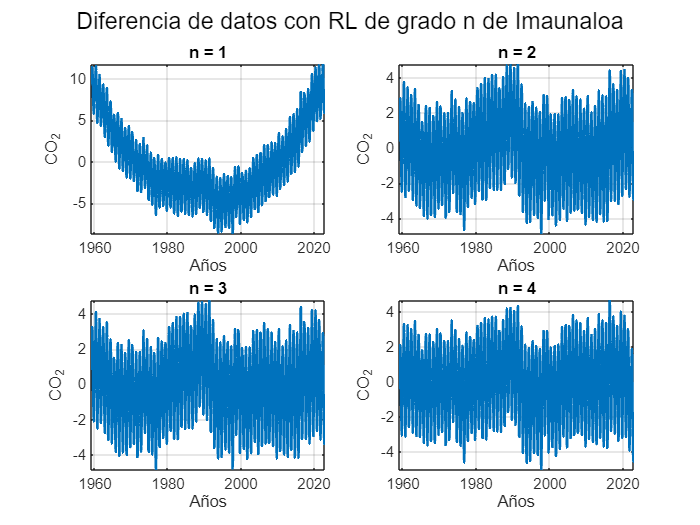


figure(4)
sgtitle('Diferencia de datos con RL de grado n de Imaunaloa')
subplot(2,2,1)
plot(D1(:,1), D1(:,2)-pv1D,'linewidth', 1.5)
grid on ; box on;
axis tight
title('n = 1')
xlabel('Años')
ylabel('CO_2')

 subplot(2,2,2)
plot(D1(:,1), D1(:,2)-pv2D,'linewidth', 1.5) 
grid on ; box on;
axis tight
title('n = 2')
xlabel('Años')
ylabel('CO_2')

subplot(2,2,3)
plot(D1(:,1), D1(:,2)-pv3D,'linewidth', 1.5)
grid on ; box on;
axis tight
title('n = 3')
xlabel('Años')
ylabel('CO_2')

subplot(2,2,4)
plot(D1(:,1), D1(:,2)-pv4D,'linewidth', 1.5) 
grid on ; box on;
axis tight
title('n = 4')
xlabel('Años')
ylabel('CO_2')